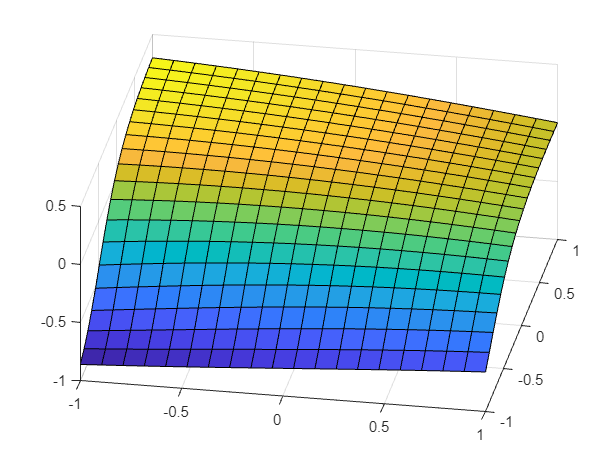

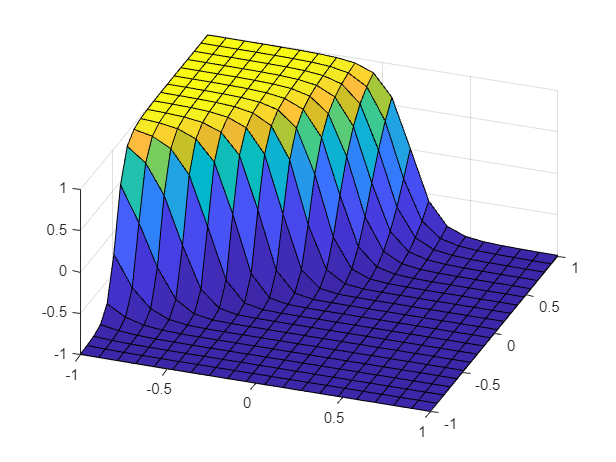

clear
close all

%parameters for the algorithm
%define the ammount of training samples in the dataset
numSamples = 25;
lern_rate = 0.1;
epochs = 100;
minibatch_size = 1;

%create dataset and according labels
x = randi(2,1,numSamples)-1;
y = randi(2,1,numSamples)-1;
true_output = double(xor(x,y));

%set zeros to -1 for tanh usage
x(x==0) = -1;
y(y==0) = -1;
true_output(true_output==0) = -1;

%set up random weights
%generate 3 weigths per neuron: two for each input/activation and one for the bias
weightsHid = randn(2,3);
weightsOut = randn(1,3);


%set up presets for algorithm
inputs = ones(3,numSamples);        %the constant input 1 for the hidden layer biases is added here
inputs([1,2],:) = [x;y];
outputHid = ones(3,numSamples);     %the constant input 1 for the output layer bias is added here
averageLoss = zeros(1,epochs);
epochalLoss = 0;
wOutSum = 0;
wHidSum = 0;
previous_deltaWeightsOut = 0;
previous_deltaWeightsHid = 0;
weightsOutSum = 0;
weightsHidSum = 0;

for e = 1:epochs
    for i = 1:numSamples
        %feedforward into hidden layer
        weightedSumHid = weightsHid * inputs(:,i);
        outputHid([1,2],i) = tanh(weightedSumHid); %put the outputs of the two hidden neurons to the vector containing the bias 1 to be able to calculate the next layer
        %feedforward into output layer
        output = tanh(weightsOut * outputHid(:,i));

        %calculate loss with square loss
        loss = 1/2 * (true_output(i) - output)^2;    %note: the factor 1/2 is there to simplify the loss functions derivative to -(target-guess). In the end by going in the negative diretion of the gradient the expression turns back to positve: deltaWeight = -lern_rate(-(target-guess)*bli*bla*blub) = lern_rate*(target - guess)*bli*bla*blub
        epochalLoss = epochalLoss + loss;

        %calculate errors for each layer
        output_error  = (true_output(:,i) - output)  .* tanhd(output);
        hidden_errors = (weightsOut' * output_error) .* tanhd(outputHid(:,i));

        %calculate weights correction values
        deltaWeightsOut = output_error * outputHid(:,i)';
        deltaWeightsHid = hidden_errors(1:2) * inputs(:,i)';
        
        %sum up the weight changes for the minibacth method
        weightsOutSum = weightsOutSum + deltaWeightsOut;
        weightsHidSum = weightsHidSum + deltaWeightsHid;

        %update weights minibatch style
        if mod(i,minibatch_size) == 0
            weightsHid = weightsHid + lern_rate.*(weightsHidSum/minibatch_size);
            weightsOut  = weightsOut  + lern_rate.*(weightsOutSum/minibatch_size);
            weightsOutSum = 0;
            weightsHidSum = 0;
        end

%         %update weights stochasticly
%         weightsHid = weightsHid + lern_rate * (deltaWeightsHid + previous_deltaWeightsHid*0.9);
%         weightsOut = weightsOut + lern_rate * (deltaWeightsOut + previous_deltaWeightsOut*0.9);

        %store current weight change to be used the next momentum term in the update equation
        previous_deltaWeightsOut = deltaWeightsOut;
        previous_deltaWeightsHid = deltaWeightsHid;

        %         drawNeuralNet(inputs(:,i),outputHid(:,i),output,weightsHid,weightsOut)
        %         hold on
        %         pause(10e-10)

    end

    res = 20;
    im = uint8(zeros(res,res,3));
    x = linspace(-1,1,res);
    y = linspace(1,-1,res);

    [X,~] = meshgrid(x);
    [~,Y] = meshgrid(y);
    Ot = zeros(res);
    for u = 1:res
        for j = 1:res
            % 2D-Image
            Input = [y(u);x(j);1];
            output = tanh(weightsOut*[tanh(weightsHid*Input);1]);
            im(u,j,:) = [(output+1)/2,(output+1)/2,(output+1)/2] .* 255;
    
            % 3D-Figure

            Input = [Y(u,j);X(u,j);1];
            Ot(u,j) = tanh(weightsOut*[tanh(weightsHid*Input);1]);
        end
    end

%     figure(1)
%     image(im)
%     pause(10e-10)

    figure(1)
    zLim = [-1 1];
    surf(Y,X,Ot)
    view(10+e*0.1,45)
    pause(10e-10)

    rander = randi(numSamples);
    figure(3);
    drawNeuralNet(inputs(:,rander),outputHid(:,rander),output,weightsHid,weightsOut);
    hold on
    pause(10e-10)
    averageLoss(e) = epochalLoss/numSamples;
    epochalLoss = 0;
end

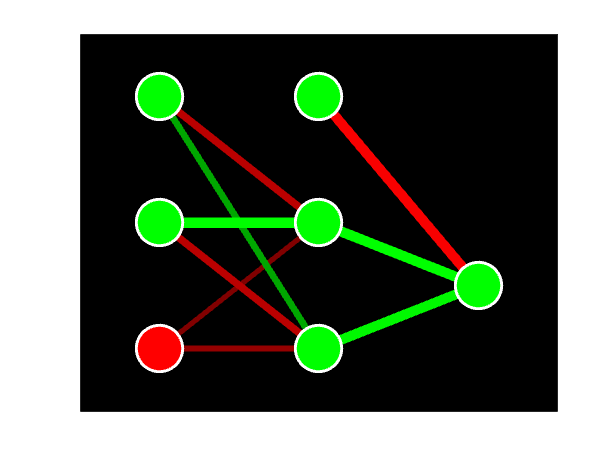

%plot evolution of loss
hold off

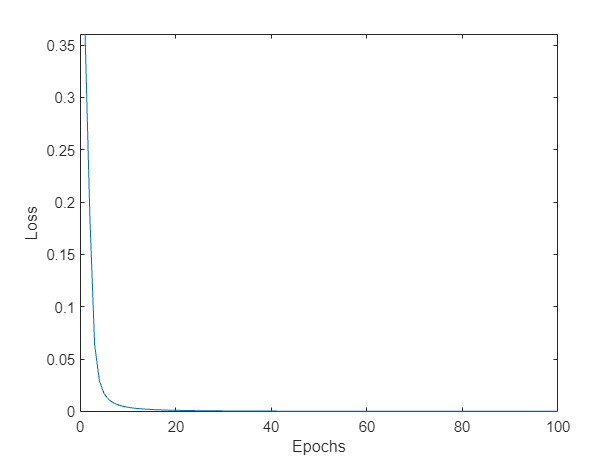

plot(1:e,averageLoss)
ylim([0,max(averageLoss)])
ylabel('Loss')
xlabel('Epochs')


%test neural network
trueInput1  = [1;-1;1];
shoudBeOne1 = tanh(weightsOut*[tanh(weightsHid*trueInput1);1])

shoudBeOne1 = -1.0000


trueInput2  = [-1;1;1];
shoudBeOne2 = tanh(weightsOut*[tanh(weightsHid*trueInput2);1])

shoudBeOne2 = 0.9897


falseInput1  = [1;1;1];
shoudBeMinusOne1 = tanh(weightsOut*[tanh(weightsHid*falseInput1);1])

shoudBeMinusOne1 = -0.9927


falseInput2  = [-1;-1;1];
shoudBeMinusOne2 = tanh(weightsOut*[tanh(weightsHid*falseInput2);1])

shoudBeMinusOne2 = -0.9912